Fuction to analyze FFT

disp("Start")

Start


x =0:.01:5;
freq1=5;
freq2=10;
freq3=5;

Generate sin of frequency 5,10,5

s1= sineGenerator(x,freq1);
s2= sineGenerator(x,freq2);
s3= sineGenerator(x,freq3);
s0 = sineGenerator(x,0);

Merge Signal

Non_Stationary = mergeSignal(s1,s0,s2,s3);
Stationary = addSignal(s1,s2,s3);
time = TimeGen(x,Non_Stationary);

Plot Signal

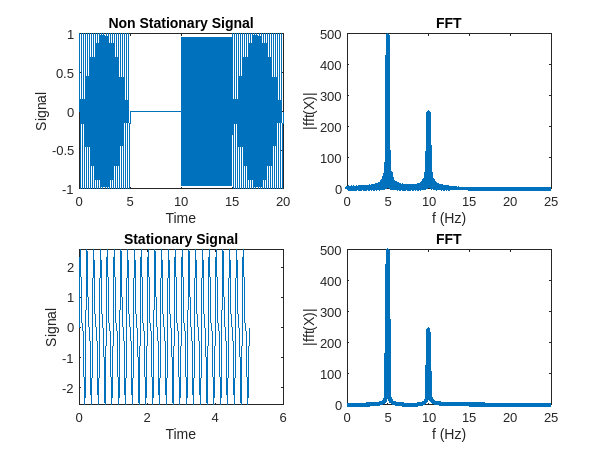

subplot(2,2,1);
plot(time, Non_Stationary)
xlabel("Time")
ylabel("Signal")
title("Non Stationary Signal")
subplot(2,2,2);
nonstatic_fft = fft(Non_Stationary);
plotfft(time, nonstatic_fft)
subplot(2,2,3);
plot(x, Stationary)
xlabel("Time")
ylabel("Signal")
title("Stationary Signal")
subplot(2,2,4);
static_fft = fft(Stationary);
plotfft(x, static_fft)

Plot seperate

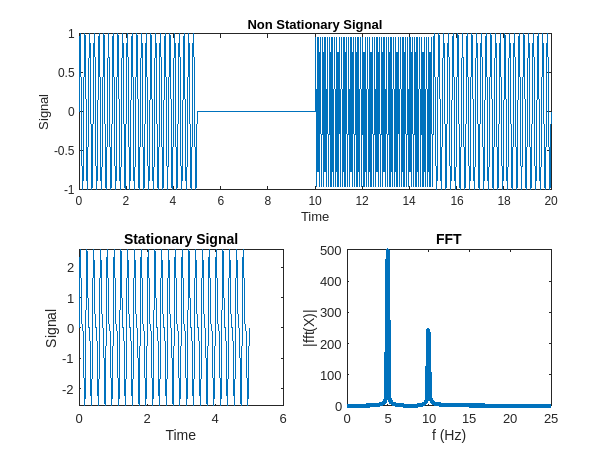

figure(1)
subplot(2,1,1);
plot(time, Non_Stationary)
xlabel("Time")
ylabel("Signal")
title("Non Stationary Signal")

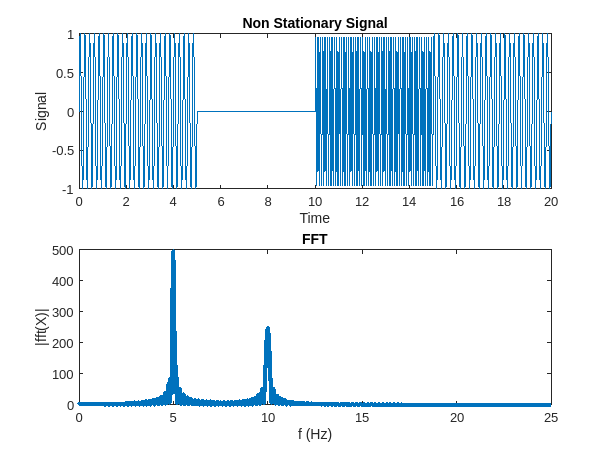

subplot(2,1,2);
plotfft(time, nonstatic_fft)

Stationary Signal

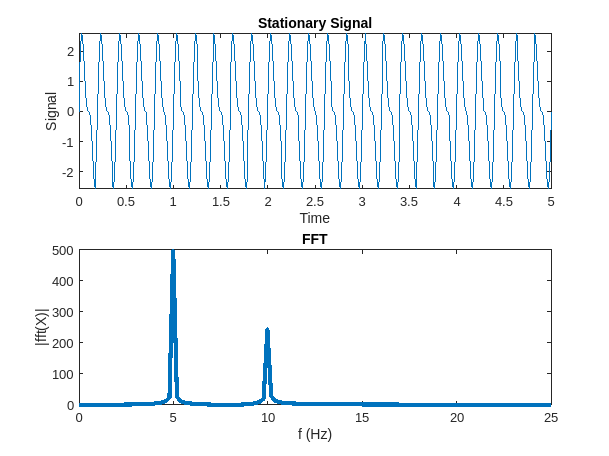

figure
subplot(2,1,1);
plot(x, Stationary)
xlabel("Time")
ylabel("Signal")
title("Stationary Signal")
subplot(2,1,2);
plotfft(x, static_fft)

figure
subplot(2,1,1);
plot(time, Non_Stationary)
xlabel("Time")
ylabel("Signal")
title("Non Stationary Signal")
subplot(2,1,2);
plotfft(time, nonstatic_fft);

Applying STFT

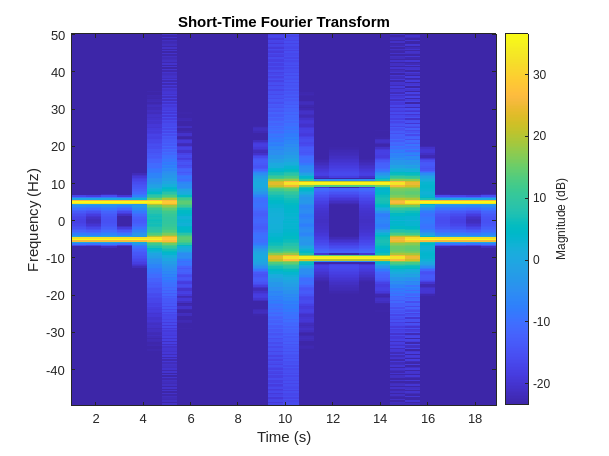

figure
fs_val = 100;
stft(Non_Stationary,fs_val, Window=kaiser(256,5))

Lets look at a more complex signal

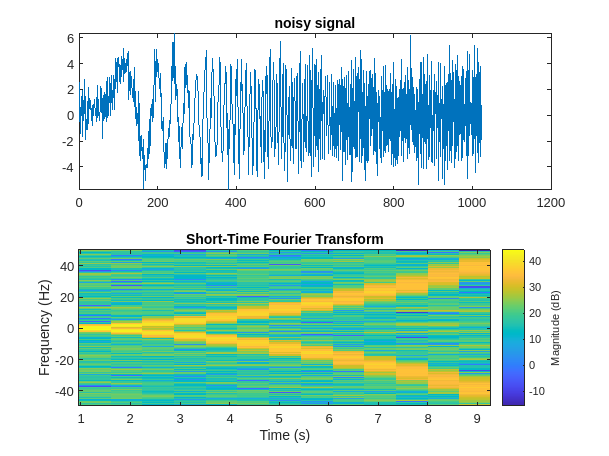

[X,XN] = wnoise('quadchirp',10,sqrt(6));
t = 0:length(X); t(end) =[];
fft_X = fft(X);
fft_XN = fft(XN);

subplot(2,1,1)
plot(t, XN); title('noisy signal');
subplot(2,1,2)
stft(XN,fs_val, Window=kaiser(256,5))

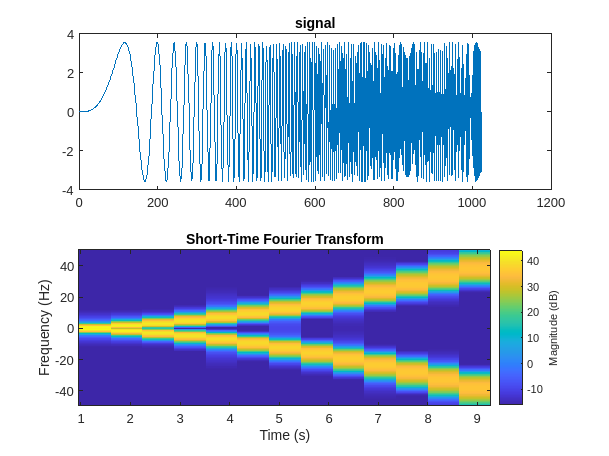

figure;
subplot(2,1,1)
plot(t, X); title('signal');
subplot(2,1,2)
stft(X, fs_val, Window=kaiser(256,5))

Applying CWT

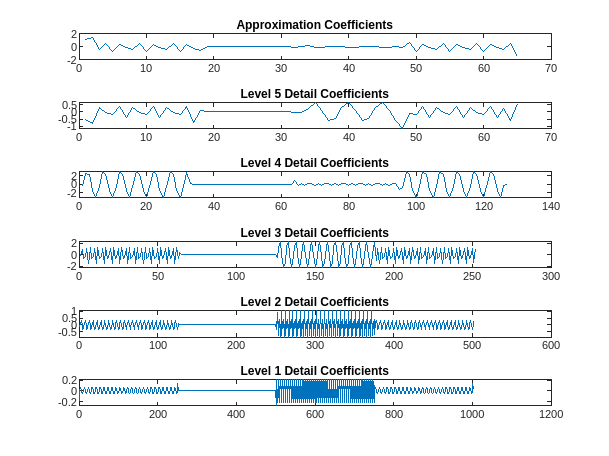

[c,l] = wavedec(Non_Stationary,5,"db2");
approx = appcoef(c,l,"db2");
[cd1,cd2,cd3, cd4, cd5] = detcoef(c,l,[1 2 3 4 5]);

tiledlayout(6,1)
nexttile
plot(approx)
title("Approximation Coefficients")
nexttile
plot(cd5)
title("Level 5 Detail Coefficients")
nexttile
plot(cd4)
title("Level 4 Detail Coefficients")
nexttile
plot(cd3)
title("Level 3 Detail Coefficients")
nexttile
plot(cd2)
title("Level 2 Detail Coefficients")
nexttile
plot(cd1)
title("Level 1 Detail Coefficients")

signal =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


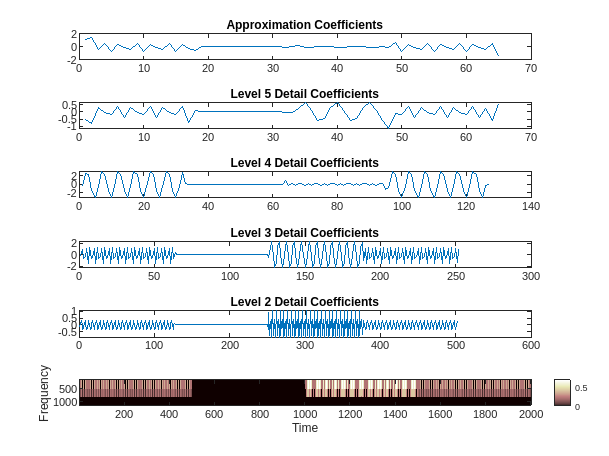

signal = Non_Stationary;
% Define parameters
scales = 1:3; % Define the range of scales for the wavelet analysis
waveletFunction = 'haar'; % Choosing a Morlet wavelet, but you can choose others
samplingFrequency = 1000; % Replace with your signal's sampling frequency

% Perform Continuous Wavelet Transform
coefficients = cwt(signal, scales, waveletFunction, 'SamplingFrequency', samplingFrequency);

% Plot the time-frequency representation
t = 1:length(signal); % Assuming time starts at 1 and increments by 1
frequencies = scal2frq(scales, waveletFunction, 1/samplingFrequency);
imagesc(t, frequencies, abs(coefficients));
xlabel('Time');
ylabel('Frequency');
colorbar;

[wt,f,coi] = cwt(signal,1);

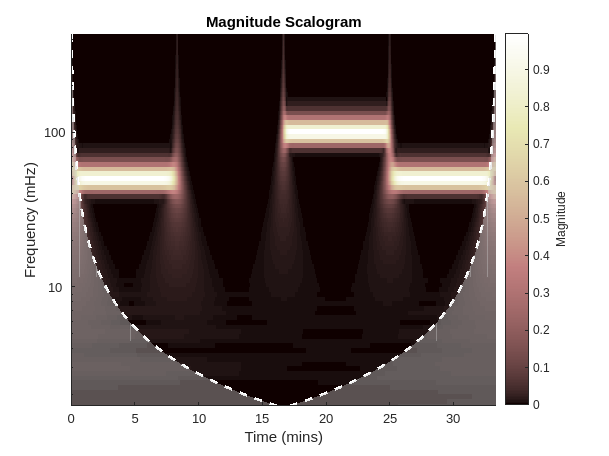

cwt(signal,1);

Function to generate Sine wave of specific frequency

function signal = sineGenerator(x, freq)
    signal = sin(2*pi*freq*x);
end


Function to plot a fft

function plotfft(x, fft)
    Fs = 1/ x(2);
    L = length(x);
    val = Fs/L*(0:L-1);
    fft = abs(fft);
    plot(val(1:round(length(val)/2)),fft(1:round(length(val)/2)),"LineWidth",3)
    xlim([0, 25])
    title("FFT")
    xlabel("f (Hz)")
    ylabel("|fft(X)|")
end

Function to merge signals

function Signal= mergeSignal(varargin)
   Signal = varargin{1};
   if nargin >1
       for i = 2:nargin
           x = varargin{i};
           Signal = [Signal, x(2:end)];
       end
   end

end

Function to add signals

function Signal= addSignal(varargin)
   Signal = varargin{1};
   if nargin >1
       for i = 2:nargin
           x = varargin{i};
           Signal = Signal + x(1:end);
       end
   end

end

Final Time Generator

function time = TimeGen(x, Signal)
    time = [0:x(2):(length(Signal)-1) * x(2)];
end
